# Taylor Series

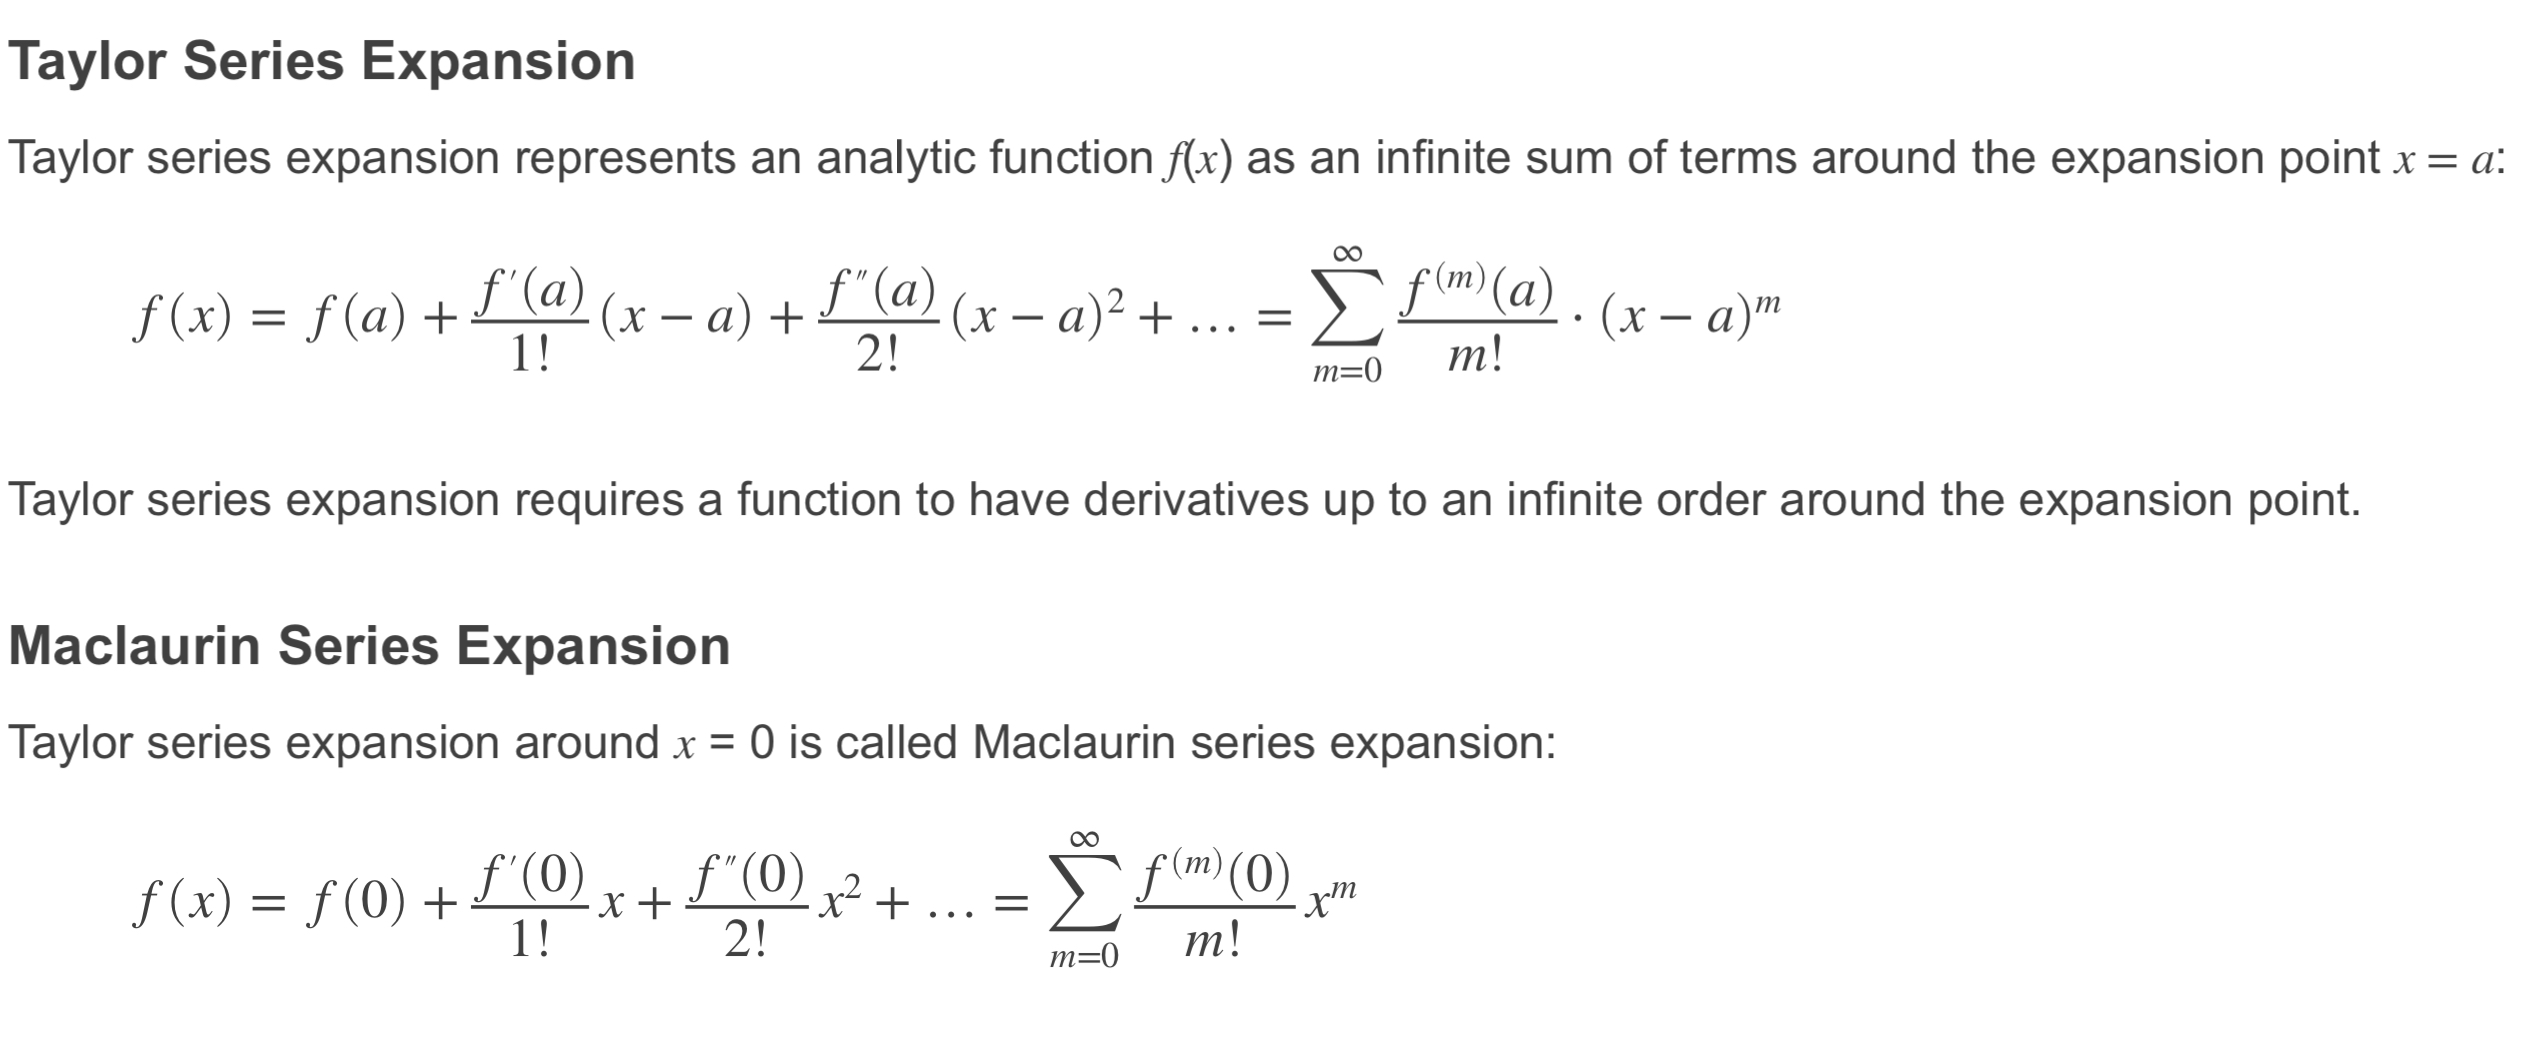

## Taylor expansion around a point

syms x
T = taylor(sin(x), x, 'ExpansionPoint', pi/4)

$$T = \frac{\sqrt{2}\,\left(x-\frac{\pi }{4}\right)}{2}+\frac{\sqrt{2}}{2}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{2}}{4}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{3}}{12}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{4}}{48}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{5}}{240}$$

x=[0:0.1:pi]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000


fx_5=sqrt(2)*0.5*...
               (+1 ...
               +(x-(pi/4)) ...
               -0.5*(x-(pi/4)).^2 ...
               -(1/6)*(x-(pi/4)).^3 ...
               +(1/24)*(x-(pi/4)).^4 ...
               +(1/120)*(x-(pi/4)).^5)

fx_5 =     0.0002    0.0999    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9855    0.9976    0.9999    0.9923    0.9751    0.9484    0.9129    0.8691    0.8176    0.7596    0.6959    0.6280    0.5573    0.4853    0.4140    0.3453    0.2816    0.2254


fx_2=sqrt(2)*0.5*(+1+(x-(pi/4)))

fx_2 =     0.1517    0.2225    0.2932    0.3639    0.4346    0.5053    0.5760    0.6467    0.7174    0.7881    0.8589    0.9296    1.0003    1.0710    1.1417    1.2124    1.2831    1.3538    1.4245    1.4952    1.5660    1.6367    1.7074    1.7781    1.8488    1.9195    1.9902    2.0609    2.1316    2.2024    2.2731    2.3438


### Plotting  

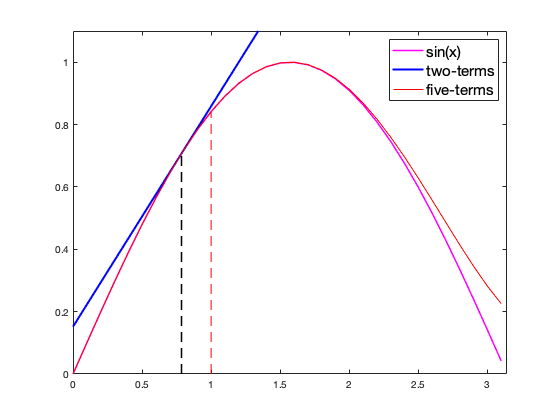

figure
plot(x, sin(x), 'm','LineWidth',1.5)
hold on
plot(x,fx_2,'b','LineWidth',2)
plot(x,fx_5,'r')
line ([pi/4 pi/4],[0 sin(pi/4)],'Color','black','LineStyle','--','lineWidth',1.5)
line ([1 1],[0 sin(1)],'Color','red','LineStyle','--')
axis([0 pi 0 1.1])
legend ('sin(x)', 'two-terms','five-terms','Fontsize',15)

### Comparing result

Value_No_Taylor= sin(1)

Value_No_Taylor = 0.8415

Value_Si_Taylor= sin(pi/4)+cos(pi/4)*(1-pi/4)

Value_Si_Taylor = 0.8589

Value_Matlab=sqrt(2)*0.5*(1+(1-(pi/4)))

Value_Matlab = 0.8589

## Taylor expansion around '0'

syms x
T = taylor(sin(x), x, 'ExpansionPoint', 0)

$$T = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

x=[0:0.1:pi]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000


fx=x-(x.^3)/6+(x.^5)/120

fx =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7834    0.8417    0.8916    0.9327    0.9648    0.9875    1.0008    1.0047    0.9995    0.9855    0.9632    0.9333    0.8968    0.8548    0.8085    0.7596    0.7096    0.6608    0.6152    0.5755    0.5444    0.5250    0.5206


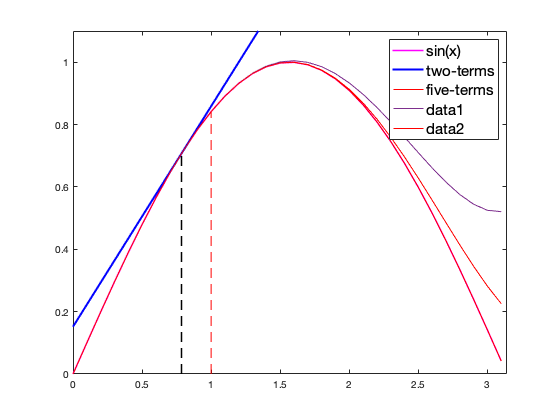

plot(x,fx)
hold on
plot(x, sin(x), 'r')

syms x
T = taylor(sin(x), x, 'ExpansionPoint', pi/4)

$$T = \frac{\sqrt{2}\,\left(x-\frac{\pi }{4}\right)}{2}+\frac{\sqrt{2}}{2}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{2}}{4}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{3}}{12}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{4}}{48}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{5}}{240}$$

x=[0:0.1:pi]

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000


fx=sqrt(2)*0.5*...
               (+1 ...
               +(x-(pi/4)) ...
               -0.5*(x-(pi/4)).^2 ...
               -(1/6)*(x-(pi/4)).^3 ...
               +(1/24)*(x-(pi/4)).^4 ...
               +(1/120)*(x-(pi/4)).^5)

fx =     0.0002    0.0999    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9855    0.9976    0.9999    0.9923    0.9751    0.9484    0.9129    0.8691    0.8176    0.7596    0.6959    0.6280    0.5573    0.4853    0.4140    0.3453    0.2816    0.2254


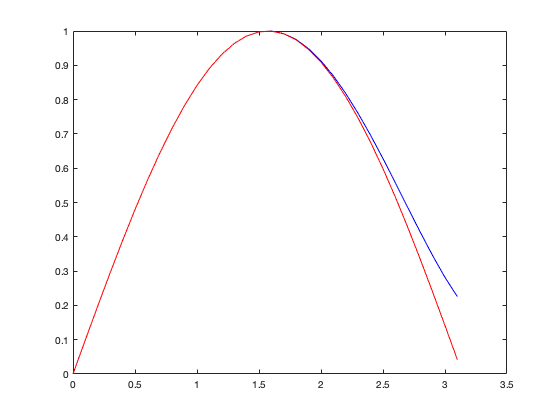


    

figure
plot(x,fx,'b')
hold on
plot(x, sin(x), 'r')